    This simulation is trying to simulate how ants follow the behavior of other ants to eventually find the shortest path to a food source.

    We start out by generating an N number of completely random paths. At each point during those paths, an ant leaves a determined bit of pheromone. The pheromones at each point on the grid accumulate as ants pass over a each point and are totalled up.

    Later when looking for the shortest path, an ant is able to determine the pheromone level at a very local level. It can detect pheromones to its left, right, upwards, and backwards. At each step in the path, the ant is looking for the direction with the highest pheromone concentration. This allows the ants to find the shortest path.

    As the number of correct paths that are generated increases, the length of the path shortens. This is what we expect to happen and decreases the randomness that happens with a low sample size.

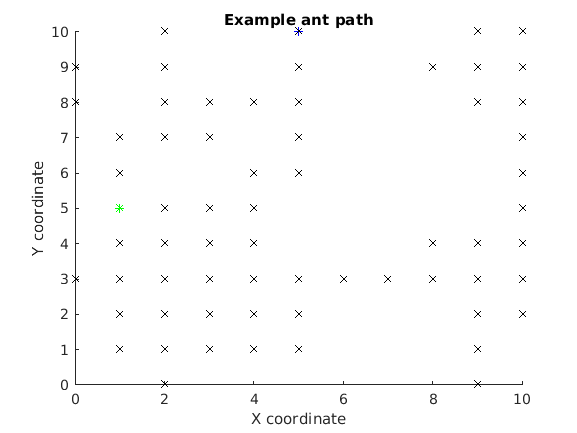

clear
close all
clc

boxSize = 10;
source = randi([0 boxSize] ,[1 2]);
dest = randi([0 boxSize] ,[1 2]);
antPos = [source(:,1) source(:,2)];
pherGrid = zeros(boxSize + 1,boxSize + 1);
% colors = ["rx","cx", "mx", "yx", "kx"];
x = 1;
y = 2;

hold on
plot(source(:,x),source(:,y), "g*")
plot(dest(:,x),dest(:,y), "b*")
xlim ([0 boxSize]);
ylim ([0 boxSize]);
title("Example ant path");
xlabel("X coordinate");
ylabel("Y coordinate");

numDirections = 3;
% Generate random correct paths
pathNum = 1000;
for i = 1:pathNum
    while (antPos(1,x) ~= dest(1,x)) || (antPos(1,y) ~= dest(1,y))
        % Generate random direction
        direction = randi([0,numDirections]);
        % Move ant in the generated direction
        if direction == 0
            antPos(:,x) = antPos(:,x) + 1;
        elseif direction == 1
            antPos(:,x) = antPos(:,x) - 1;
        elseif direction == 2
            antPos(:,y) = antPos(:,y) + 1;
        elseif direction == 3
            antPos(:,y) = antPos(:,y) - 1;
        end
        % Periodic boundary condition
        if antPos(:,x) > 10
            antPos(:,x) = 0;
        elseif antPos(:,x) < 0
            antPos(:,x) = 10;
        elseif antPos(:,y) > 10
            antPos(:,y) = 0;
        elseif antPos(:,y) < 0
            antPos(:,y) = 10;
        end
        
        pherGrid(antPos(1,x) +1 , antPos(1,y) + 1) = pherGrid(antPos(1,x) +1 , antPos(1,y) + 1) + 1; 
        if i == 1
            plot(antPos(:,x), antPos(:,y), "kx")
            pause(0.1);
        end
%         plot(antPos(:,x),antPos(:,y), colors(mod(i,4) + 1))
    end
    antPos = [source(:,1) source(:,2)];
end
hold off;

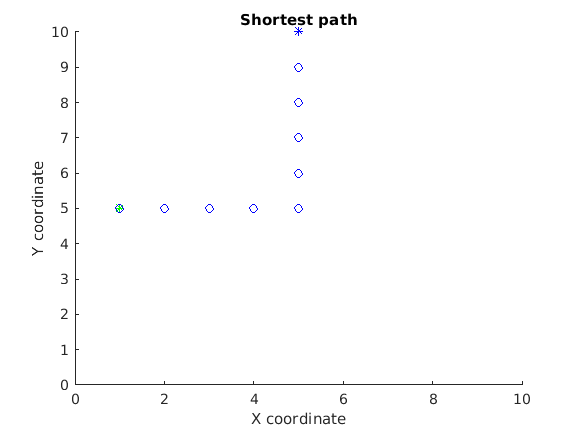


% Reset ant position and change pheromones levels for the source and dest
antPos = [dest(:,1) dest(:,2)];

originalPherGrid = pherGrid;
pherGrid(dest(1,x) + 1, dest(1,y) + 1) = pherGrid(dest(1,x) + 1, dest(1,y) + 1) - 100;
pherGrid(source(1,x) + 1, source(1,y) + 1) = pherGrid(source(1,x) + 1, source(1,y) + 1) + 100;

% Create a path from the food to the source based on the previous correct
% paths
figure;
hold on
plot(source(:,x),source(:,y), "g*")
plot(dest(:,x),dest(:,y), "b*")
xlim ([0 boxSize]);
ylim ([0 boxSize]);

% Loop until the ant reaches the source
while (antPos(1,x) ~= source(1,x)) || (antPos(1,y) ~= source(1,y))
    antPos;
    % Calculate the corresponding x and y values on the pheromone grid
    pherGridX = antPos(1,x) + 1;
    if pherGridX > 11
        pherGridX = 1;
    end
    pherGridY = antPos(1,y) + 1;
    if pherGridY > 11
        pherGridY = 1;
    end
    % Calculate the left, right, up, and down values on the pheromone grid
    leftX = pherGridX -1;
    if leftX < 1
        leftX = 11;
    end
    left = pherGrid(leftX, pherGridY);
    rightX = pherGridX + 1;
    if rightX > 11
        rightX = 1;
    end
    right = pherGrid(rightX, pherGridY);
    upY = pherGridY + 1;
    if upY > 11
        upY = 1;
    end
    up = pherGrid(pherGridX, upY);
    downY = pherGridY - 1;
    if downY < 1
        downY = 11;
    end
    down = pherGrid(pherGridX, downY);
    % Find the maximum of the left, right, up, and down.
    values = [left right up down];
    highest = max(values);
    % Change the ants position based on the highest pheromone value
    if highest == left
        antPos(1,x) = antPos(1,x) - 1;
        if antPos(1:x) < 0
            antPos(1:x) = 10;
        end
    elseif highest == right
        antPos(1,x) = antPos(1,x) + 1;
        if antPos(1:x) > 10
            antPos(1:x) = 0;
        end
    elseif highest == up
        antPos(1,y) = antPos(1,y) + 1;
        if antPos(1:y) > 10
            antPos(1:y) = 0;
        end
    elseif highest == down
        antPos(1,y) = antPos(1,y) - 1;
        if antPos(1:y) < 0
            antPos(1:y) = 10;
        end
    end
    if antPos(:,x) > 10
        antPos(:,x) = 0;
    elseif antPos(:,x) < 0
        antPos(:,x) = 10;
    elseif antPos(:,y) > 10
        antPos(:,y) = 0;
    elseif antPos(:,y) < 0
        antPos(:,y) = 10;
    end
    pherGrid(pherGridX, pherGridY) = 0;
    
    plot(antPos(:,x),antPos(:,y), "bo");
    pause(.1);
end

title("Shortest path");
xlabel("X coordinate");
ylabel("Y coordinate");
hold off;

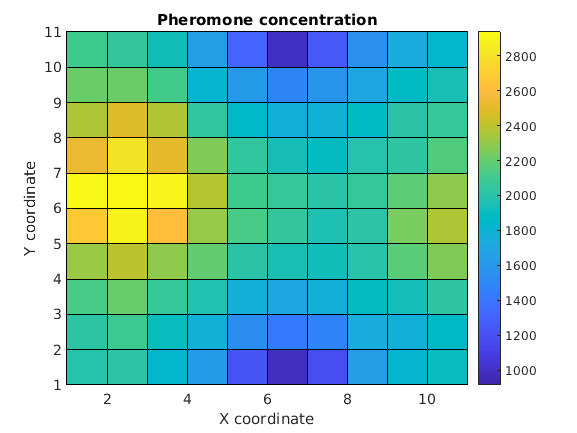


pcolor(originalPherGrid.');
title("Pheromone concentration");
xlabel("X coordinate");
ylabel("Y coordinate");
colorbar;